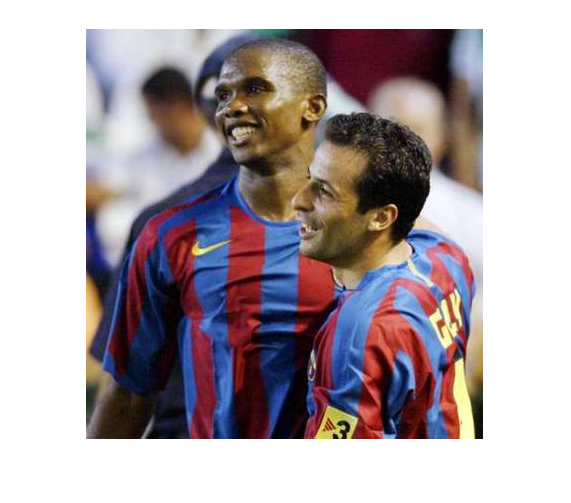

im = imread('probes/probaB5.jpg');
im2 = imread('probes/probaB1.jpg');
im3 = imread('probes/probaB6.jpg');
im4 = imread('probes/probaB6.jpg');

imshow(im);

tam = 75;
[HModelHist, SModelHist] = getHists(im, tam);
[HModelHist2, SModelHist2] = getHists(im2, tam);
[HModelHist3, SModelHist3] = getHists(im3, tam);
[HModelHist4, SModelHist4] = getHists(im4, tam);

HModelHist = (HModelHist + HModelHist2 + HModelHist3 + HModelHist4)/4;
SModelHist = (SModelHist + SModelHist2 + SModelHist3 + SModelHist4)/4;

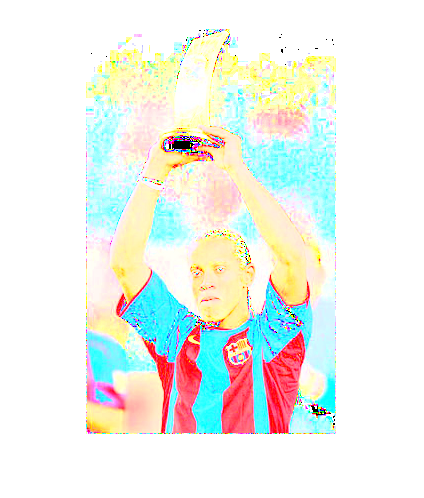

im = imread('probes/probaB2.jpg');
r = im(:,:,1);
g = im(:,:,2);
b = im(:,:,3);

I = (double(r) + double(g) + double(b))/3;
red = double(r)./I;
gre = double(g)./I;
blu = double(b)./I;
im = cat(3, red, gre, blu);

imshow(im);

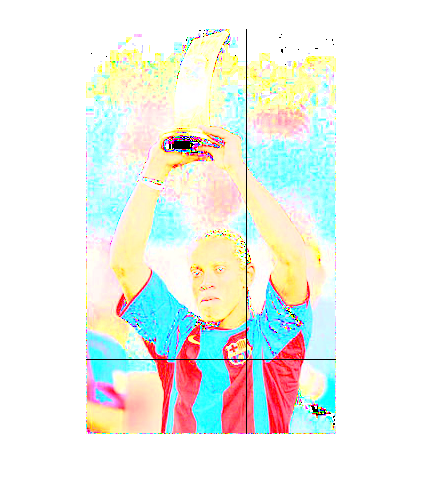

[c, f] = centerr(im, 3);
[cc, ff] = centerr(im, 1);

c = uint16((cc+c)/2);
f = uint16((ff+f)/2);

im(:,c,:) = 0;
im(f,:,:) = 0;
imshow(im)

### Ajustem paràmetres d'error amb algunes imatges de prova

cercaEquip(HModelHist, SModelHist, imread('probes/probaD1.jpg')) 

errH = 2.3133e+03

errS = 8.3225e+03

ans = logical
   0


cercaEquip(HModelHist, SModelHist, imread('probes/probaD2.jpg')) 

errH = 7.2500e+03

errS = 2.4925e+03

ans = logical
   0


cercaEquip(HModelHist, SModelHist, imread('probes/probaD3.jpg')) 

errH = 5.4043e+03

errS = 2.1473e+03

ans = logical
   0


cercaEquip(HModelHist, SModelHist, imread('probes/probaD4.jpg')) 

errH = 4.0551e+03

errS = 1.1062e+04

ans = logical
   0


cercaEquip(HModelHist, SModelHist, imread('probes/probaD5.jpg')) 

errH = 4.2584e+03

errS = 3.6977e+03

ans = logical
   0


cercaEquip(HModelHist, SModelHist, imread('probes/probaD6.jpg')) 

errH = 4.5175e+03

errS = 3.3841e+03

ans = logical
   0


cercaEquip(HModelHist, SModelHist, imread('probes/probaD7.jpg')) 

errH = 7.1266e+03

errS = 1.3931e+03

ans = logical
   1


cercaEquip(HModelHist, SModelHist, imread('probes/probaD8.jpg'))

errH = 6.8129e+03

errS = 987.9166

ans = logical
   1



cercaEquip(HModelHist, SModelHist, imread('probes/probaB1.jpg')) 

errH = 2.4083e+03

errS = 703.9241

ans = logical
   1


cercaEquip(HModelHist, SModelHist, imread('probes/probaB2.jpg')) 

errH = 4.2287e+03

errS = 1.5080e+03

ans = logical
   1


cercaEquip(HModelHist, SModelHist, imread('probes/probaB3.jpg')) 

errH = 1.6530e+03

errS = 4.9818e+03

ans = logical
   1


cercaEquip(HModelHist, SModelHist, imread('probes/probaB4.jpg')) 

errH = 1.6777e+03

errS = 870.6834

ans = logical
   1


cercaEquip(HModelHist, SModelHist, imread('probes/probaB5.jpg')) 

errH = 5.8108e+03

errS = 2.3965e+03

ans = logical
   0


cercaEquip(HModelHist, SModelHist, imread('probes/probaB6.jpg')) 

errH = 1.7828e+03

errS = 913.1786

ans = logical
   1


cercaEquip(HModelHist, SModelHist, imread('probes/probaB7.jpg')) 

errH = 3.6030e+03

errS = 2.2786e+03

ans = logical
   1


cercaEquip(HModelHist, SModelHist, imread('probes/probaB8.jpg'))

errH = 1.3544e+03

errS = 3.5711e+03

ans = logical
   1


### Calculem tests

correct = 0;
correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB1.jpg'));

errH = 2.0897e+03

errS = 1.5934e+03

correct = 1

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB2.jpg'));

errH = 2.7295e+03

errS = 1.2464e+03

correct = 2

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB3.jpg'));

errH = 2.4049e+03

errS = 782.8429

correct = 3

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB4.jpg'));

errH = 1.9590e+03

errS = 3.3953e+03

correct = 4

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB5.jpg'));

errH = 5.1654e+03

errS = 1.3965e+03

correct = 5

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB6.jpg'));

errH = 5.4722e+03

errS = 3.3415e+03

correct = 5

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB7.jpg'));

errH = 3.0497e+03

errS = 1.2514e+03

correct = 6

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB8.jpg'));

errH = 2.4146e+03

errS = 1.5829e+03

correct = 7

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB9.jpg'));

errH = 2.2488e+03

errS = 2.0659e+03

correct = 8

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB10.jpg'));

errH = 2.7389e+03

errS = 1.0998e+03

correct = 9

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB11.jpg'));

errH = 2.1999e+03

errS = 1.2327e+03

correct = 10

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB12.jpg'));

errH = 6.1346e+03

errS = 1.5677e+03

correct = 10

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB13.jpg'));

errH = 1.1060e+03

errS = 2.0179e+03

correct = 11

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB14.jpg'));

errH = 4.5775e+03

errS = 7.1545e+03

correct = 11

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB15.jpg'));

errH = 3.7139e+03

errS = 1.9086e+03

correct = 12

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB16.jpg'));

errH = 3.0509e+03

errS = 1.0636e+04

correct = 12

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB17.jpg'));

errH = 2.2252e+03

errS = 5.2175e+03

correct = 12

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB18.jpg'));

errH = 3.3839e+03

errS = 1.8948e+03

correct = 13

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB19.jpg'));

errH = 4.4934e+03

errS = 2.4601e+03

correct = 14

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB20.jpg'));

errH = 3.0177e+03

errS = 2.1915e+03

correct = 15

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB21.jpg'));

errH = 6.5049e+03

errS = 876.7776

correct = 16

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB22.jpg'));

errH = 3.0511e+03

errS = 2.6489e+03

correct = 17

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB23.jpg'));

errH = 4.3998e+03

errS = 3.3048e+03

correct = 17

correct = correct + cercaEquip(HModelHist, SModelHist, imread('testFinal/testB24.jpg'));

errH = 4.1510e+03

errS = 2.9502e+03

correct = 17


display("Positius correctes");

    "Positius correctes"



correct

correct = 17


display("Falsos negatius");

    "Falsos negatius"



incorrect = 24-correct

incorrect = 7



correct = 24;
correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD1.jpg'));

errH = 3.2799e+03

errS = 2.8825e+03

correct = 23

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD2.jpg'));

errH = 5.6444e+03

errS = 2.4807e+03

correct = 23

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD3.jpg'));

errH = 5.2199e+03

errS = 5.8628e+03

correct = 23

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD4.jpg'));

errH = 5.3703e+03

errS = 5.2293e+03

correct = 23

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD5.jpg'));

errH = 7.0551e+03

errS = 1.1459e+04

correct = 23

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD6.jpg'));

errH = 4.3106e+03

errS = 8.8184e+03

correct = 23

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD7.jpg'));

errH = 6.4312e+03

errS = 6.2405e+03

correct = 23

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD8.jpg'));

errH = 9.0506e+03

errS = 7.5910e+03

correct = 23

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD9.jpg'));

errH = 2.2709e+03

errS = 3.4270e+03

correct = 22

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD10.jpg'));

errH = 7.7194e+03

errS = 7.6873e+03

correct = 22

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD11.jpg'));

errH = 8.5768e+03

errS = 2.7187e+03

correct = 22

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD12.jpg'));

errH = 4.3030e+03

errS = 6.3407e+03

correct = 22

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD13.jpg'));

errH = 1.0169e+03

errS = 4.8231e+03

correct = 21

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD14.jpg'));

errH = 4.1314e+03

errS = 6.9426e+03

correct = 21

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD15.jpg'));

errH = 6.6225e+03

errS = 2.7137e+03

correct = 21

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD16.jpg'));

errH = 7.6301e+03

errS = 3.4053e+03

correct = 21

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD17.jpg'));

errH = 3.1034e+03

errS = 2.1866e+03

correct = 20

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD18.jpg'));

errH = 6.1950e+03

errS = 2.5092e+03

correct = 20

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD19.jpg'));

errH = 4.8461e+03

errS = 2.1885e+03

correct = 20

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD20.jpg'));

errH = 8.0334e+03

errS = 1.1699e+03

correct = 19

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD21.jpg'));

errH = 1.3015e+03

errS = 2.3140e+03

correct = 18

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD22.jpg'));

errH = 4.1811e+03

errS = 3.7623e+03

correct = 18

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD23.jpg'));

errH = 2.8251e+03

errS = 7.3594e+03

correct = 18

correct = correct - cercaEquip(HModelHist, SModelHist, imread('testFinal/testD24.jpg'));

errH = 4.7346e+03

errS = 2.8625e+03

correct = 18


display("Positius incorrectes");

    "Positius incorrectes"



correct

correct = 18


display("Falsos positius");

    "Falsos positius"



incorrect = 24-correct

incorrect = 6

### Funcions

Donada una matriu 3D i una dimensió Z, troba la intersecció entre els màxims de la suma de valors en cada eix X - Y. Per l'eix X, suma el conjunt de components en l'eix Y i retorna la posició del màxim, el mateix per a l'eix Y.

function [c, f] = centerr(im, d)

    [x,y] = size(im(:,:,1));
    res = zeros(1,y);
    sum(im(:,1,2));
    max = 0;
    for i = [1:y]
        res(1, i) = nansum(im(:,i,d));
        if (res(1,i) > max)
            c = i;
            max = res(1, i);
        end
    end
    max = 0;
    res = zeros(1,x);
    for i = [1:x]
        res(1, i) = nansum(im(i,:,d));
        if (res(1,i) > max)
            f = i;
            max = res(1, i);
        end
    end
end

Donada una imatge 3D i dues dimensions, cerca el màxim de l'eix X i Y i fa la mitja.

function [c, f] = colCenter(im, d1, d2)

    [c, f] = centerr(im, d1);
    [cc, ff] = centerr(im, d2);
    
    c = uint16((cc+c)/2);
    f = uint16((ff+f)/2);

end

Donada la imatge i el tamany d'un quadrat, es cerca el centre de màxima concentració en les dimensions R i B i retorna els histogrames de H i S respectivament de la imatge amb quadrat de tamany "tam".

function [hHist, sHist] = getHists(im, tam)
       

    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = (double(r) + double(g) + double(b))/3;
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    imcat = cat(3, red, gre, blu);
    
    [c, f] = colCenter(imcat, 1, 3);
    %tam = 75;
    
    im = rgb2hsv(im);
    h = im(:,:,1);
    s = im(:,:,2);
    v = im(:,:,3);
    im = cat(3, h, s, v);
    
    im(:,:,2) = uint8(normalize(im(:,:,2), 'range')*100); %S
    im(:,:,1) = uint16(normalize(im(:,:,1), 'range')*360); %H
    
    
    hHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 1, im);
    sHist = SaturationHistogram(f-tam, f+tam, c-tam, c+tam, 2, im);

end

Donades 4 coordenades dins la imatge HSV, una dimensió i la imatge, retorna l'histograma de 33 bins de la dimensió donada de la imatge.

hi ha una funció per Saturation i una per Color

function model = colorHistogram(xini, xfin, yini, yfin, color, im)
    model = zeros(1, 46);
    for i = [yini:yfin]
        for j = [xini:xfin]
            model(1, uint16(im(j, i, color)/8)+1) = model(1, uint16(im(j, i, color)/8)+1) + 1;
        end
    end
    %bar(model);
end

function model = SaturationHistogram(xini, xfin, yini, yfin, color, im)
    model = zeros(1, 26);
    for i = [yini:yfin]
        for j = [xini:xfin]
            model(1, uint8(im(j, i, color)/4)+1) = model(1, uint8(im(j, i, color)/4)+1) + 1;
        end
    end
    %bar(model);
end

function D = distChiSq( X, Y )

    m = size(X,1);  
    n = size(Y,1);
    mOnes = ones(1,m); 
    D = zeros(m,n);
    
    for i=1:n
      yi = Y(i,:);  
      yiRep = yi( mOnes, : );
      s = yiRep + X;    
      d = yiRep - X;
      D(:,i) = sum( d.^2 ./ (s+eps), 2 );
    end
    D = D/2;
end

function result = cercaEquip(HModelHist, SModelHist, im)
    
    [x, y] = size(im(:,:,1));
    
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = (double(r) + double(g) + double(b))/3;
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    imcat = cat(3, red, gre, blu);
    [c, f] = colCenter(imcat, 1, 3);
    
    result = false;
    tam = 75;
    fma = f+tam;
    fmi = f-tam;
    cmi = c-tam;
    cma = c+tam;
    if((f+tam)> x)
        fma = x;
        fmi = x-(tam*2);
        if(fmi < 1) 
            fmi = 1;
        end
    elseif((f-tam) < 1)
        fmi = 1;
        fma = 1+(tam*2);
        if(fma > x) 
            fma = x;
        end
    end
    
    if((c+tam)> y)
        cma = y;
        cmi = y-(tam*2);
        if(cmi < 1) 
            cmi = 1;
        end
    elseif((c-tam) < 1)
        cmi = 1;
        cma = 1+(tam*2);
        if(cma > y) 
            cma = y;
        end
    end
    
    
    im = rgb2hsv(im);
    h = im(:,:,1);
    s = im(:,:,2);
    v = im(:,:,3);
    im = cat(3, h, s, v);
    
    im(:,:,1) = uint16(normalize(im(:,:,1), 'range')*360); %H
    im(:,:,2) = uint8(normalize(im(:,:,2), 'range')*100); %S
    
    HImgeHist = colorHistogram(fmi, fma, cmi, cma, 1, im);
    SImgeHist = SaturationHistogram(fmi, fma, cmi, cma, 2, im);
            
    errH = distChiSq(HImgeHist, HModelHist);
    errS = distChiSq(SImgeHist, SModelHist);

    errH
    errS
    
    
    res = 0;
    
    if (errH < 3500 && errS < 2000)
        res = res + 4;
    end
    
    
    if (errH > 4000 && errS > 3500)
        res = res -4;
    end
    
    
    if ((errH + errS) < 7000)
        res = res + 5;
    else
        if ((errH - errS) > 4000) 
            res = res;
        else 
            res = res -2;
        end
    end
    
    
    if (errH > 2800)
        if (errH > 5000)
            res = res - 3;
        else
        res = res - 1;
        end
    end
    
    
    if (errH < 3500)
        if (errH < 2800)
            res = res + 3;
        else
        res = res + 1;
        end
    end
    
    
    if (errS > 4000)
        if (errS > 5000)
            res = res - 4;
        else
        res = res -2;
        end
    end
    
    
    if (errS < 2600)
        if (errS < 1500)
            res = res + 5;
        else
        res = res + 2;
        end
    end
    
   
    
    if (res > 0)
        result = true;
    else
        result = false;
    end
    
end